bin_hand = imread("binarize_hand64.ppm");
verilog_med = imread("out_00.ppm");
bin_hand = bin_hand(:,:,1);
verilog_med = verilog_med(:,:,1);

matlab_med = medfilt2(bin_hand, [5,5]);
matlab_med(1:2,:)=0; matlab_med(63:64,:)=0; matlab_med(:,1:2)=0; matlab_med(:,63:64)=0;
matlab_med(matlab_med > 0) = 255;

diff = imabsdiff(matlab_med, verilog_med);
diff_sum = sum(sum(sum(diff)))

diff_sum = 255

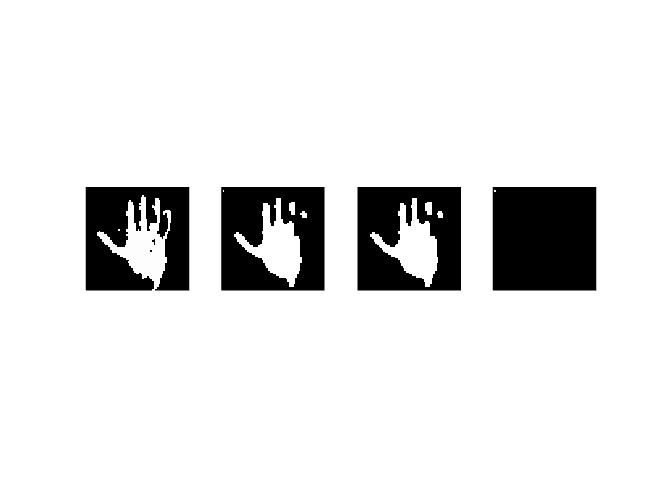


figure;
subplot(1,4,1);
imshow(bin_hand);
subplot(1,4,2);
imshow(verilog_med);
subplot(1,4,3);
imshow(matlab_med);
subplot(1,4,4);
imshow(diff);